## Solve the PDE with homogeneous Dirichlet problem in 2D.

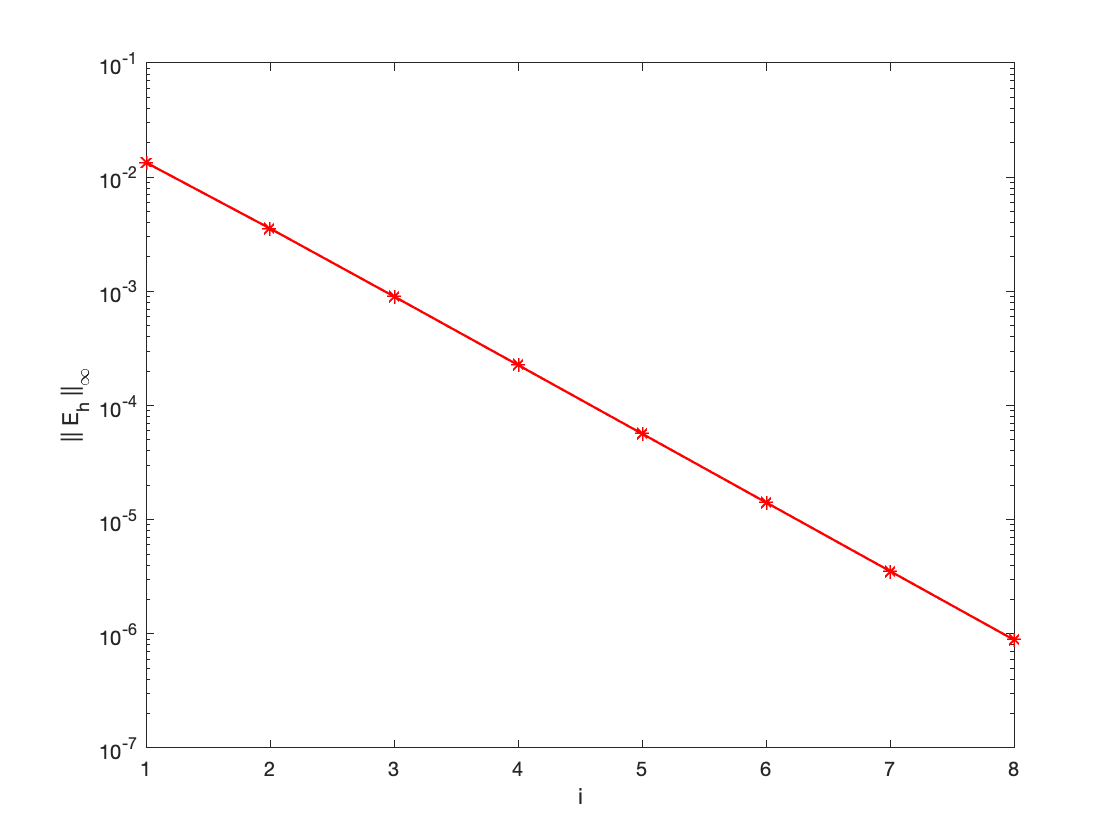

f = @(x, y) 1 + 0*x;


fun1 = @(x,y,k) sin(k*pi*(1+x)/2);
fun2 = @(x,y,k) k^3*sinh(k*pi);
fun3 = @(x,y,k) sinh(k*pi*(1+y)/2);
fun4 = @(x,y,k) sinh(k*pi*(1-y)/2);

norms = zeros(8, 1);

for i = 1 : 8
    n = 2^i;
    [X, Y, h] = createGrid(n);
    F = rhs(f, X, Y);
    A = fdm2D(n);
    U_h = solveHomogeneousDirichlet2D(A, F);
    U_h = U_h(:); %numerical sol for interior points
    
    m = size(X,1);
    U = zeros(m, m);
    for g = 1:m
        for j=1:m
            x = X(g,j);
            y = Y(g,j);
            sum = 0;
            for k = 1:2:200
                eval = (fun1(x,y,k)/fun2(x,y,k))*(fun3(x,y,k)+fun4(x,y,k)); 
                if isnan(eval)
                    eval = 0;
                end
            sum = sum + eval;
            end
            U(g,j) = ((1-x^2)/2) - (16/(pi^3)) * sum;
        end
    end
    U = U(:); %analytical sol for interior points
    
    norms(i) = norm(U-U_h,'inf');
end

%%
semilogy(norms, 'r*-', 'LineWidth', 1.2);
xlabel('i')
ylabel('|| E_h ||_\infty')


%%we except the scale factor equals to 4 because we used the second order
%%apprximate
norms(1:end-1)./norms(2:end)

ans =     3.7794
    3.9396
    3.9845
    3.9961
    3.9990
    3.9998
    3.9999


## Definition of functions part

Create the interior point list

function [X, Y, h] = createGrid(n)
   h = 1/n;
   x = (1-n:n-1)/n;
   [X,Y] = meshgrid(x);
end

Left hand side

function A = fdm2D(n)
    % Assemble the finite difference stiffness matrix in 2D, only for
    % internal points
    h = 1/n;
    m = 2*n - 1; %number of grid internal nodes of matrix
    s = m^2; %size of matrix A
    
    
    o = ones(m, 1);
    small_matrix = spdiags([-o 4*o -o], -1:1, m, m);
    A = speye(m);
    o = ones(s, 1);
    A = 1/h^2 * (kron(A, small_matrix) + spdiags([-o -o], [-m m], s, s));
end

Right hand side


function F = rhs(func, X, Y)
    F = func(X, Y);
    F = F(:);
end

PDE solver with homogenous Dirichlet boundary condition


function U = solveHomogeneousDirichlet2D(A, F)
%solves the system of internal grid points AU = F*h^2, obtaining the
%discretized solution of the PDE
%(adds the zero boundaries to the discr. solution)
U = A\F;
m = sqrt(length(F));
U = reshape(U, [m m]); %show the discretized solution as a matrix

% add zero boundary
% vertical_vec = zeros(m, 1);
% U = [vertical_vec U vertical_vec];
% horiz_vec = [0 vertical_vec' 0];
% U = [horiz_vec; U; horiz_vec];
end